# FILTROS FIR CON MATALAB 

Para ralizar estos filtros se utlilizara la funcion b=fir1(n,Wn)

donde 

**n:**orden del filtro 

Wn:Frecuancia de corte normalizada [0 ... 1]

b: coeficiontes FIR

Por defecto usa ventana de hamming, si queremos usar otras ventanas 

b=fir1(n,wn,hanning(n+1))

b=fir1(n,wn,barlett(n+1))

## Ejemplo 1

Queremos diseñar un filtro que corte a un 1KHz, con una frecuencia de muestreo de 48KHz, queremos un filtro con 200 puntos

fc=1000;
fs=48000;
%Nos dara 201 puntos
%La frecuencia en matlab esta normalizada , desde 0 a 1 donde 1 es la mitad
%de la frecuencia de muestreo
b=fir1(200,fc/(fs/2));
hold on;
grid on;
plot(b,"r")

Se puede observar que el filtro es simetrico ya que es una caracteristica del filtros implementados con ventanas., proviene de la trasnfromada inversa del filtro que se desea el cual es un rectangulo el cual tiene como inversa una funcion semenjante a sinc

## Ejemplo 2 

Implementar el filtro del ejemplo 1 con la ventana de Hanning;

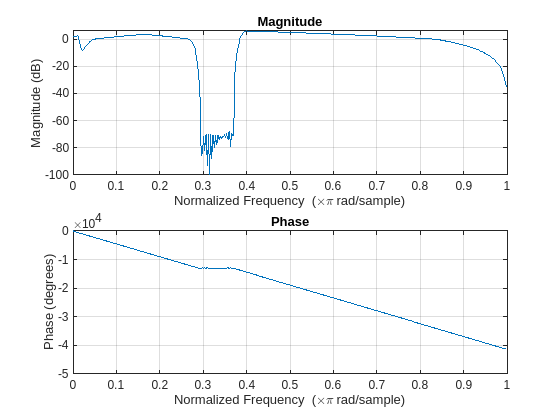

b2=fir1(200,fc/(fs/2),hanning(201));
plot(b2,"b")
hold off;

Respuesta en frecuencia con la funcion freqz(b,a,L)

donde

 a: son los coefinciantes (en este caso no hay y se pone 1)

L: es la longitud 

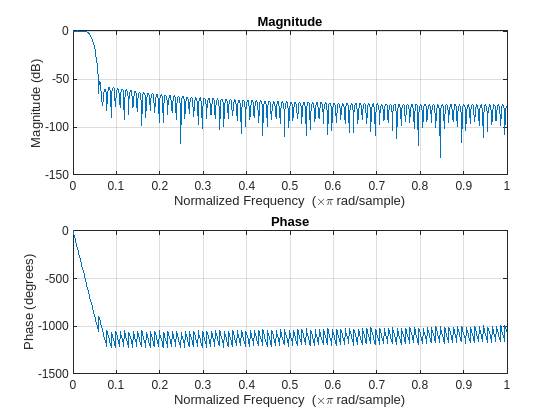

freqz(b,1,1024)

Como se observa la magnitud cae a una frecuencia normalizada de 0.058 radianes/muestra y su fase es completamente lineal.

Ahora se calcula ra respuesta impulsional .H Y T son el ?

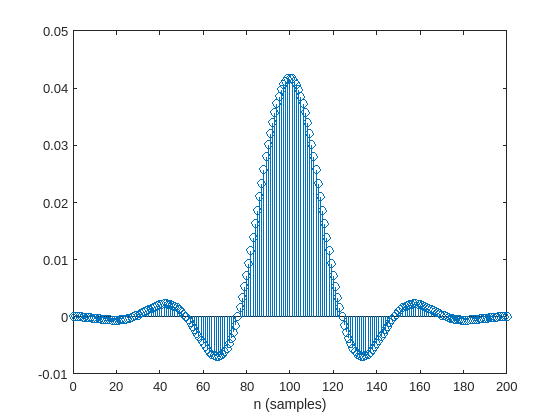

[H,T]=impz(b,1);
stem(T,H);xlabel("n (samples)")

## Ejemplo 3

Filtro paso banda con wn= [w1 w2] donde w1 y w2 son las frecuencias de corte 

fss=2000;
b2= fir1(200,[fc/(fs/2),fss/(fs/2)])

b2 =     0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001    0.0000    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0010    0.0012    0.0012    0.0013    0.0013    0.0012    0.0010    0.0007    0.0004   -0.0000   -0.0004   -0.0009   -0.0014   -0.0019   -0.0023   -0.0026   -0.0028   -0.0030   -0.0029   -0.0028   -0.0025   -0.0021   -0.0016   -0.0011   -0.0005    0.0000    0.0005    0.0008    0.0011    0.0011    0.0011


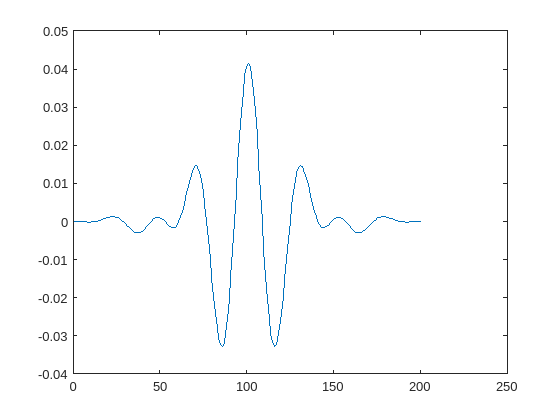

plot(b2)

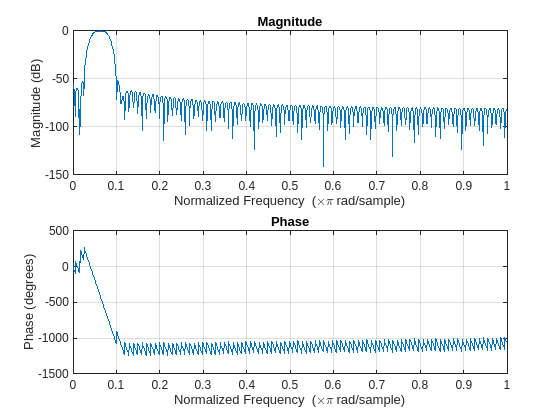

freqz(b2,1,1024)

## Ejemplo 4

Diseño filtro FIR arbitrario con FIR 2  

b = fir2(n, f, m) donde f es el vector de frecuencias de interes , y m es la magnitud de dichas frecuencias de interes, f debe ir desde 0 hasta 1. Los valores de f que no se especifiquen se obtienen por interpolación, esta frecuencia esta en hercios

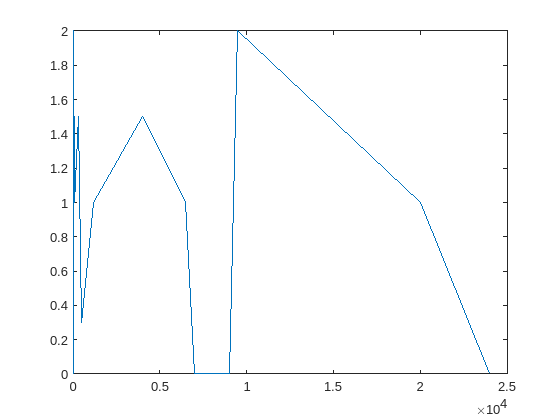

frec_sample=48000;
f = [0 20 40 100 300 500 1200 4000 6500 7000 9000 9500 20000 24000];
m = [0 1  2  1   1.5 0.3 1    1.5  1    0    0    2    1     0];
figure();
plot(f,m);

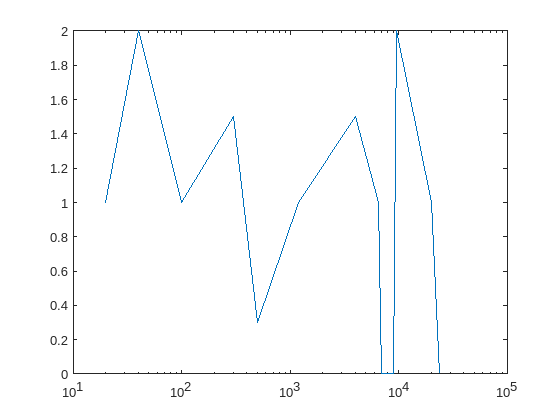

figure();
semilogx(f,m);

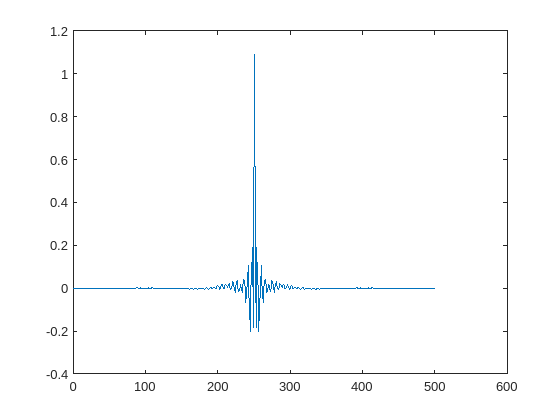

b3=fir2(500,f./(frec_sample/2),m);
plot(b3)

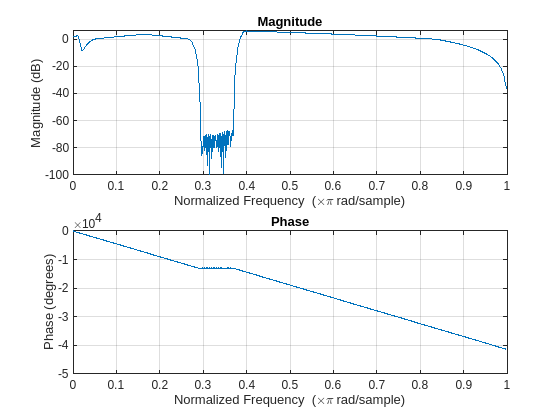

freqz(b3,1,1024);

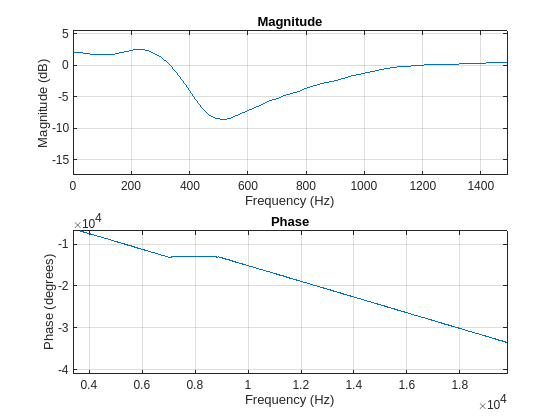

%Con el parametro de frec sample se muestra el bode en analogico 
freqz(b3,1,1024,frec_sample);

## Filtrado de una señal con u filtro FIR O IIR

Y=filter(b,a,x)

x=señal de entrada

y=señal de salida filtrada

b,a= coeficnientes FIR/IIR

# FILTROS IIR

[b,a]=butter(n,wn)

[b,a]=cheby1(n,Rp,wn)

[b,a]=cheby2(n,Rs,wn)

[b,a]=elip(n,Rp,Rs,wn)

[b,a]=besself(n,wn) (fase lineal enlas bandas pasantes  , solo tienen polos no ceros la banda de caida es muy lenta )

n:orden dle filtro

wn:frecuencia normalizada

a:coeficientes recursivos

b:coeficientes no recursivos

R,Rp,Rs: rizado de namdas de paso o atenuada(en decibelios)